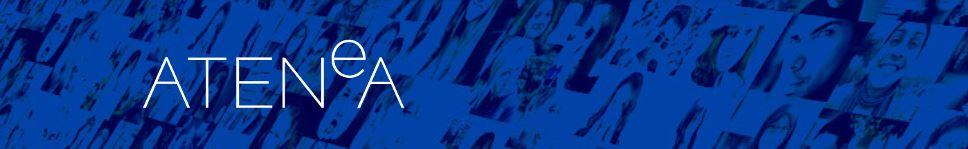

## Pràctica 2

Genereu 20 punts de la forma $\left(x_i ,y_i \right)$ tals que $y_i =J_o \left(x_i \right)$, on


$$J_0 \left(x\right)=\frac{1}{\pi }\int_0^{\pi } \cos \left(x\int t\right)\textrm{dt}$$


és la funció de Bessel d’ordre zero i les $x_i$ són de l’interval $\left\lbrack -3,3\right\rbrack$ i equiespaiades. Utilitzeu la funció $\textrm{besselj}\left(0,x_i \right)$ de Matlab.

**Es demana:**

`(a)` Calculeu l’aproximació per mínims quadrats d’aquest conjunt de punts emprant polinomis de grau des de $1$fins a $10$. Feu una estimació de l’error que es produeix en els punts intermedis comparant el resultat d’avaluar els polinomis aproximadors amb els resultats exactes que es poden obtenir amb Matlab.

`(b) `Com que la funció de Bessel $J_0 \left(x\right)$ és una funció parell, calculeu l’aproximació per polinomis només amb termes parell, és a dir, de la forma


$$\textrm{erf}\left(t\right)\approx c_0 +c_1 x^2 +c_2 x^4 +\;\ldotp \ldotp \ldotp \;+c_n x^{2n}$$


Feu, també, una estimació de l’error produit.

`(c) `Finalment, calculeu l’aproximació del conjunt de punts sota el criteri de mínims quadrats i per un polinomi del tipus

Estudieu com es comporta l’error per a aquesta nova aproximació i compareu aquest resultat amb els anteriors.


$$J_0 \left(x\right)\approx c_0 +c_1 {\left(x/3\right)}^2 +c_2 {\left(x\right./\left.3\right)}^4 +\;\ldotp \ldotp \ldotp \;+c_n {\left(x/3\right)}^{2n}$$


`(d)` Presenteu els resultats de cada apartat en una taula. Comenteu i argumenteu els resultats obtinguts.

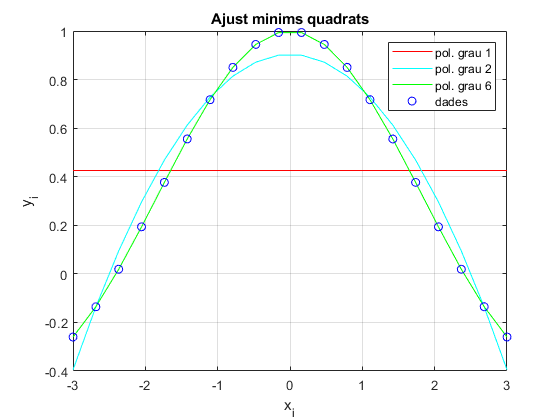

% Generació 20 punts (xi,yi)
x = linspace(-3,3,20);
y = besselj(0,x);

% Polinomis mínims quadrats de 1 a 10
errors = zeros(10,1);
%    coeff polinomi;  y values polinomi; estimació d'error
p1 = polyfit(x,y,1); y1 = polyval(p1,x); errors(1) = norm(y1-y);
p2 = polyfit(x,y,2); y2 = polyval(p2,x); errors(2) = norm(y2-y);
p3 = polyfit(x,y,3); y3 = polyval(p3,x); errors(3) = norm(y3-y);
p4 = polyfit(x,y,4); y4 = polyval(p4,x); errors(4) = norm(y4-y);
p5 = polyfit(x,y,5); y5 = polyval(p5,x); errors(5) = norm(y5-y);
p6 = polyfit(x,y,6); y6 = polyval(p6,x); errors(6) = norm(y6-y);
p7 = polyfit(x,y,7); y7 = polyval(p7,x); errors(7) = norm(y7-y);
p8 = polyfit(x,y,8); y8 = polyval(p8,x); errors(8) = norm(y8-y);
p9 = polyfit(x,y,9); y9 = polyval(p9,x); errors(9) = norm(y9-y);
p10 = polyfit(x,y,10); y10 = polyval(p10,x); errors(10) = norm(y10-y);

% Visualitzatció emprant alguns polinomis
plot(x,y1,'r');
hold on
grid on
plot(x,y2,'c');
plot(x,y6,'g');
plot(x,y,'bo');
title('Ajust minims quadrats');
xlabel('x_i'); ylabel('y_i');
legend('pol. grau 1','pol. grau 2','pol. grau 6', 'dades');
hold off

% Taula d'errors segons el grau del polinomi
R = [(1:10)',errors];
T = array2table(R,'VariableNames',{'grau polinomi','error'}); disp(T)

    grau polinomi      error   
    _____________    __________

          1              1.9395
          2              0.3508
          3              0.3508
          4            0.024846
          5            0.024846
          6          0.00088644
          7          0.00088644
          8           1.788e-05
          9           1.788e-05
         10          2.1391e-07



#### COMENTARIS

Veient la taula anterior, observem que a major grau de polinomi es comet menys error, aproximant-se així a la funció de Bessel en l'interval donat. 

També ens adonem que els errors amb grau $x\;$parell i el grau $x+1$obtenen el mateix error i això es degut a que la funció de Bessel és una funció parell (*s'ha resolt l'apartat b*). Si ens fixem en els polinomis generats només tenen els termes parells i els termes senars tenen coefficient cero.

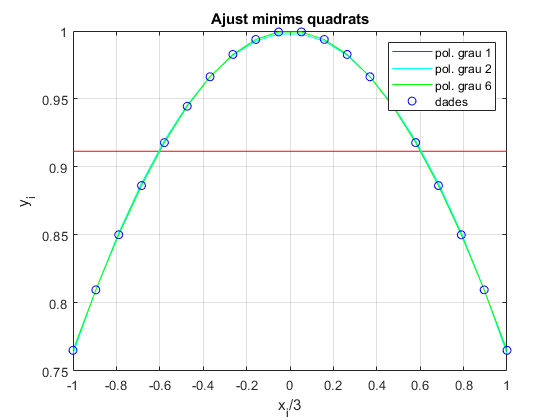

x = linspace(-3,3,20);
x = x/3;
y = besselj(0,x);
% Polinomis mínims quadrats de 1 a 10 (parells)
errorsc = zeros(6,1);
%    coeff polinomi;  y values polinomi; estimació d'error
p1 = polyfit(x,y,1); y1 = polyval(p1,x); errorsc(1) = norm(y1-y);
p2 = polyfit(x,y,2); y2 = polyval(p2,x); errorsc(2) = norm(y2-y);
p4 = polyfit(x,y,4); y4 = polyval(p4,x); errorsc(3) = norm(y4-y);
p6 = polyfit(x,y,6); y6 = polyval(p6,x); errorsc(4) = norm(y6-y);
p8 = polyfit(x,y,8); y8 = polyval(p8,x); errorsc(5) = norm(y8-y);
p10 = polyfit(x,y,10); y10 = polyval(p10,x); errorsc(6) = norm(y10-y);

% Visualitzatció emprant els mateixos polinomis que en l'apartat anterior
plot(x,y1,'r');
hold on
grid on
plot(x,y2,'c');
plot(x,y6,'g');
plot(x,y,'bo');
title('Ajust minims quadrats');
xlabel('x_i/3'); ylabel('y_i');
legend('pol. grau 1','pol. grau 2','pol. grau 6', 'dades');
hold off

% Taula d'errors segons el grau del polinomi per x/3
R = [[1,2,4,6,8,10]',errorsc];
T = array2table(R,'VariableNames',{'grau polinomi','error'}); disp(T)

    grau polinomi      error   
    _____________    __________

          1             0.34607
          2           0.0060398
          4          4.3734e-05
          6          1.6432e-07
          8          3.5466e-10
         10          4.5841e-13



% Comparació dels erros entre apartats
errorsa = [errors(1),errors(2),errors(4),errors(6),errors(8),errors(10)]';
R = [[1,2,4,6,8,10]',errorsa, errorsc, abs(errorsa-errorsc)];
T = array2table(R,'VariableNames',{'grau polinomi','error x_i','error x_i/3', '|error x_i - error x_i/3|'}); disp(T)

    grau polinomi    error x_i     error x_i/3    |error x_i - error x_i/3|
    _____________    __________    ___________    _________________________

          1              1.9395       0.34607                1.5934        
          2              0.3508     0.0060398               0.34476        
          4            0.024846    4.3734e-05              0.024802        
          6          0.00088644    1.6432e-07            0.00088628        
          8           1.788e-05    3.5466e-10             1.788e-05        
         10          2.1391e-07    4.5841e-13            2.1391e-07        



#### COMENTARIS

En la anterior taula es pot observar l'error comès en l'apartat **b** (*error x_i*), i l'error comès en l'apartat **c** (*error x_i/3*). Com podiem deduir com l'apartat **a**, a major grau de polinomi es comet menys error. Però si ens fixem amb la nova aproximació de dividir les x entre 3, es comet molt menys error, fixant-nos en la taula el valor d'error es la meitat que en l'apartat **b**, això es pot veure clarament en els gràfics on el pol.grau 2 en l'apartat **a** no cobría totes les dades (*hi ha força error*), en canvi amb aquesta última gràfica pol.grau 2 si que sembla que cobreix totes les dades.